# Загрузка, обработка и визуализация экспериментальных данных

**Самостоятельная работа**

Обработайте данные по среднесуточной температуре в Москве за 2017 год.

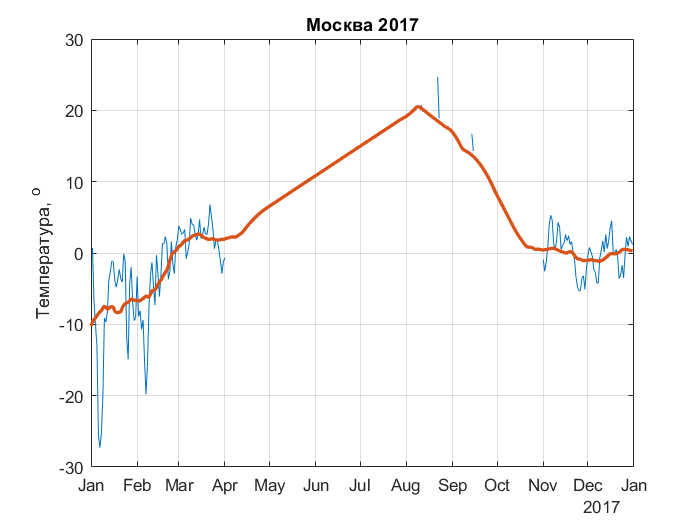

## Чтение данных

1. Считайте данные из файла `tempdata.csv` в переменную `T` типа `table`

T = readtable('tempdata.csv');

2. Постройте график среднесуточной температуры (столбец `TAVG`) в зависимости от даты измерения. Переменная `h1` должна содержать указатель на график

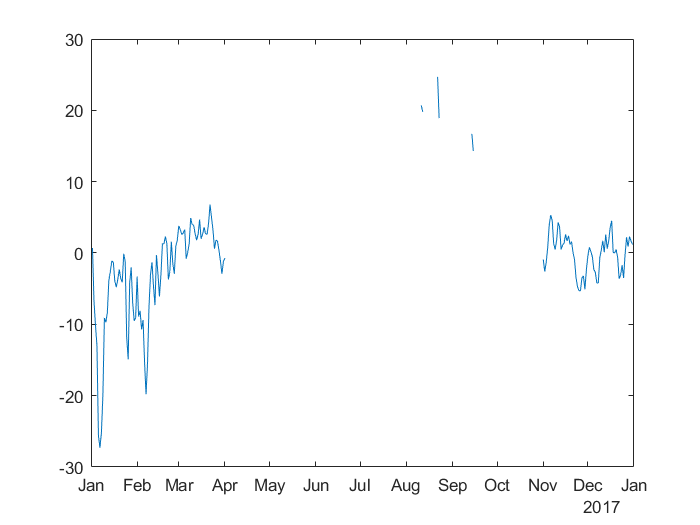

h1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×365 datetime]
              YData: [1×365 double]
              ZData: [1×0 double]

  Show all properties


h1 = plot(T.DATE, T.TAVG);

## Статистический анализ

3. В пеменную `Tmin` запишите минимальную среднесуточную температуру (минимальное значение `TAVG`), а в переменную `Tmax` - максимальную

Tmin = min(T.TAVG);
Tmax = max(T.TAVG);

4. На основании полученных данных посчитайте диапазон изменения (разброс) среднесуточной температуры. Результат запишите в переменную `Trange`

Trange = Tmax - Tmin;

5. На графике видно, что данные содержат много пропусков. В переменную `N` запишите количество пропущенных значений в столбце `TAVG`

N = nnz(ismissing(T.TAVG));

## Обработка данных

6. Заполните пропуски в таблице T методом линейной интерполяции

T = fillmissing(T, 'linear');

7. Выделите общий характер изменения среднесуточной температуры в Москве за 2017 год. Для этого сгладьте данные в столбце `TAVG` методом скользящего среднего по 30 точкам (дням). Результат запишите в новый столбец `TAVG2`

T.TAVG2 = movmean(T.TAVG, 30);

## Визуализация данных

8. На уже построенный график `TAVG` от `DATE` добавьте график столбца `TAVG2` (его линия должна иметь толщину** 2**). Переменная `h2` должна содержать указатель на график

hold on
h2 = plot(T.DATE, T.TAVG2, 'LineWidth', 2);
hold off

9. Включите сетку по обеим осям

grid on

10. Добавьте заголовок графика: **Москва 2017**

title('Москва 2017')

11. Подпишите ось ординат: **Температура, ^o**

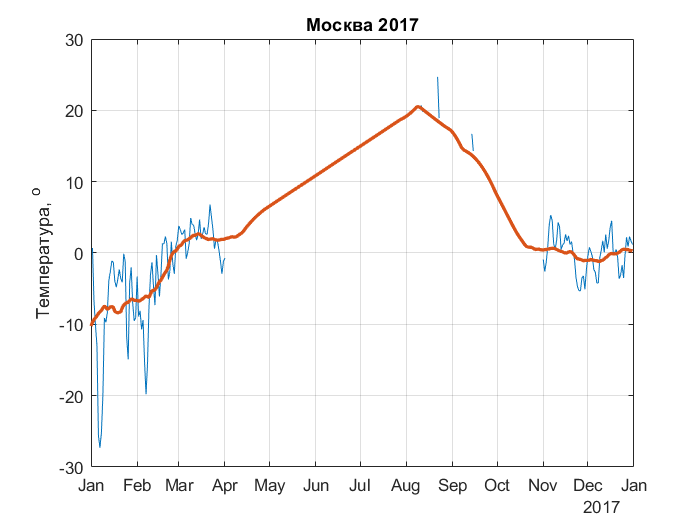

ylabel('Температура, ^o')

*2018 © ЦИТМ Экспонента*